# Total Planner Simulation

## function import

addpath("./env/");
addpath("./env/map/");
addpath("./utils/");
addpath("./graph_search/");
addpath("./sample_search/");
addpath("./local_planner/");
addpath("./animation/");

## initialize

clc; clear; close all;

% load environment
load("gridmap_20x20_scene1.mat");
map_size = size(grid_map);
G = 1;

% start and goal (pose)
start = [3, 2, 0];
goal = [18, 29, pi / 2];

% planner
global_planner_name = "a_star";
local_planner_name = "pid";

## path planning

global_planner = str2func(global_planner_name);
[path, global_flag, cost, expand] = global_planner(grid_map, start(:, 1:2), goal(:, 1:2));

## planning visualization

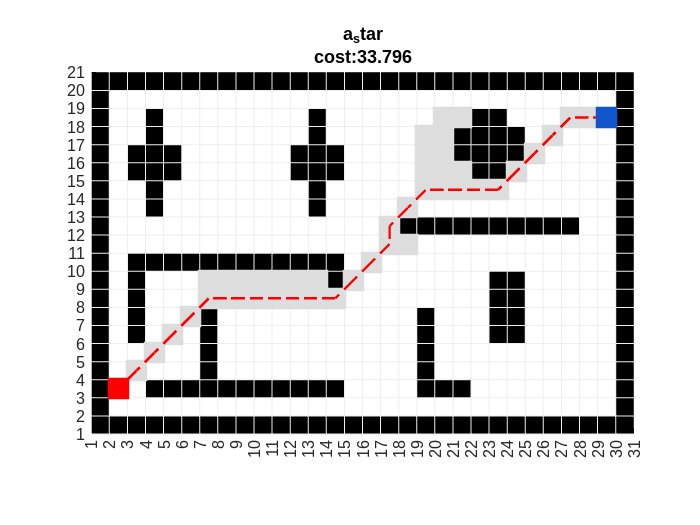

clf;
hold on

% plot map
plot_grid(grid_map);
plot_expand(expand, map_size, G, global_planner_name);
plot_path(path, G);

% plot start and goal
plot_square(start, map_size, G, "#f00");
plot_square(goal, map_size, G, "#15c");

title([global_planner_name, "cost:" + num2str(cost)]);

hold off

## path tracking

local_planner = str2func(local_planner_name);
[pose, local_flag] = local_planner(path, start, goal);

## tracking visualization

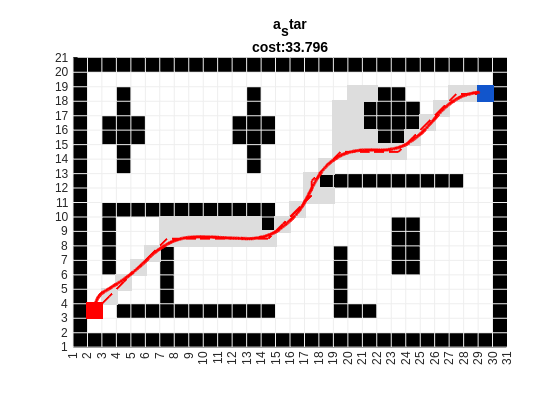

% animation
animation = str2func("animation_" + local_planner_name);
traj = []; record_video = false;
animation(pose, traj, G / 2, record_video);

hold off